Lab3

uppgift 1)

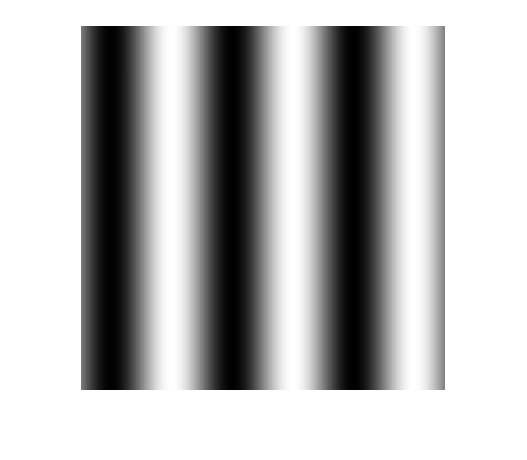

clear
clf

colormap('gray');
for r=1:512
    	    for c=1:512
        	    B1(r,c)=uint8(128-127*sin(2*pi*3*c/512));
        	    B2(r,c)=uint8(128-127*sin(2*pi*45*c/512));
                B3(r,c)=uint8(128-127*sin(2*pi*90*c/512));
    	   end
end
	figure(1); 
    imshow(B1); 

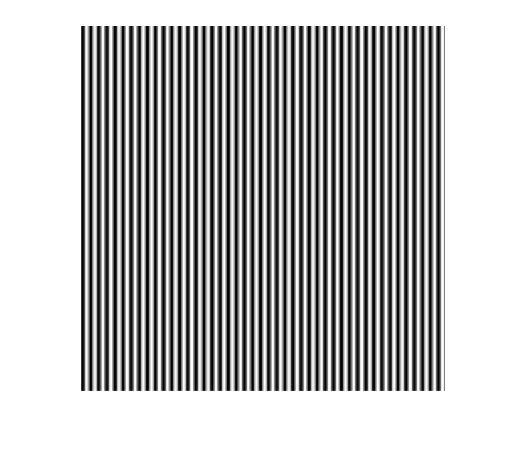

    figure(2); 
    imshow(B2);

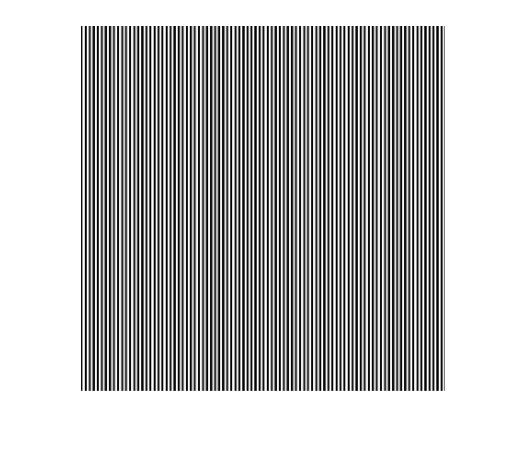

    figure(3);
    imshow(B3);

uppgift 2)

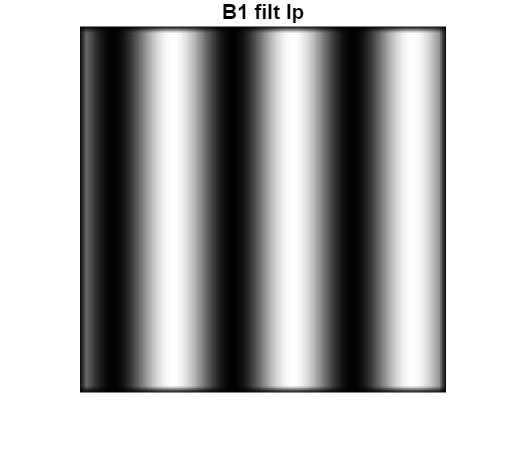

clf


h_lp = (1/100)*ones(10,10);
h_hp = [1 0 -1; 2 0 -2; 1 0 -1];

B1_filt_lp = uint8(conv2(single(h_lp),single(B1)));
B1_filt_hp = uint8(conv2(single(h_hp),single(B1)));

B2_filt_lp = uint8(conv2(single(h_lp),single(B2)));
B2_filt_hp = uint8(conv2(single(h_hp),single(B2)));

B3_filt_lp = uint8(conv2(single(h_lp),single(B3)));
B3_filt_hp = uint8(conv2(single(h_hp),single(B3)));

figure(4); imshow(B1_filt_lp); title('B1 filt lp');

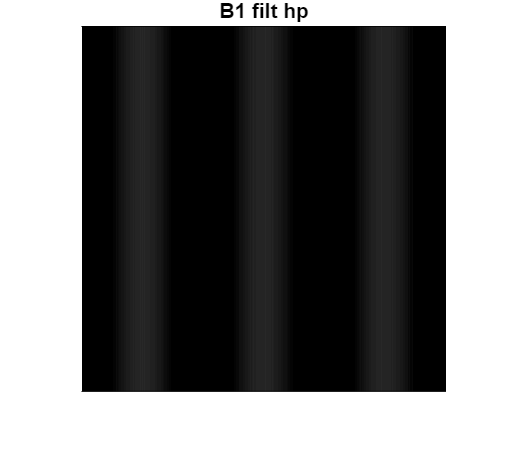

figure(5); imshow(B1_filt_hp); title('B1 filt hp');

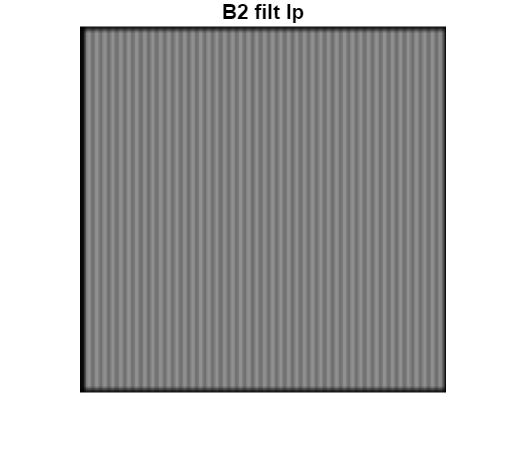


figure(6); imshow(B2_filt_lp); title('B2 filt lp');

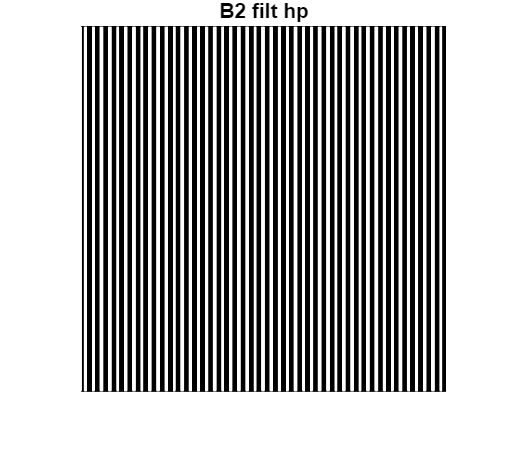

figure(7); imshow(B2_filt_hp); title('B2 filt hp');

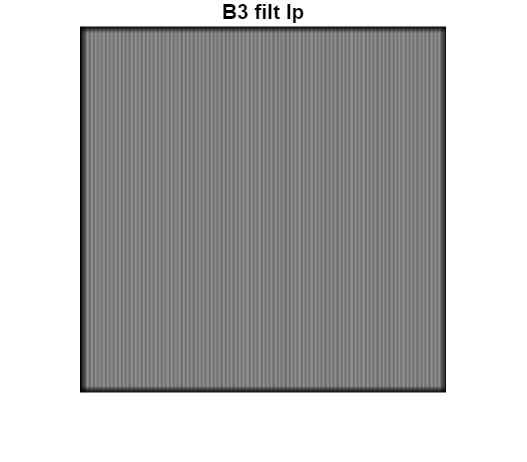


figure(8); imshow(B3_filt_lp); title('B3 filt lp');

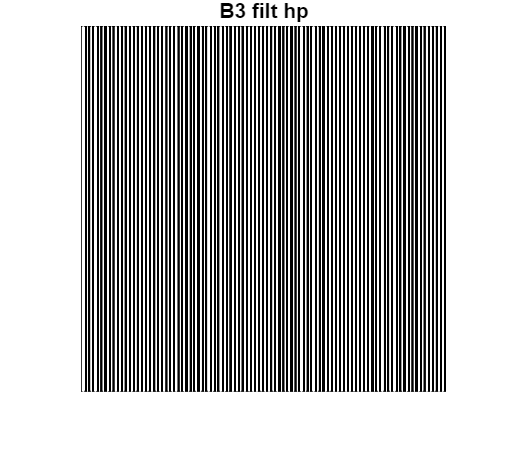

figure(9); imshow(B3_filt_hp); title('B3 filt hp');

uppgift 3)

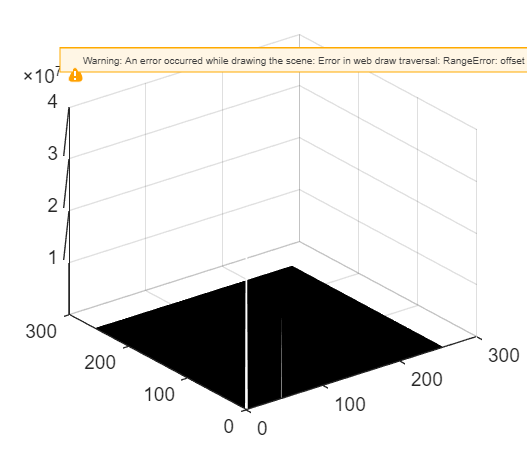

clf

B_frek = fft2(B2);
mesh(abs(B_frek(1:256, 1:256)));

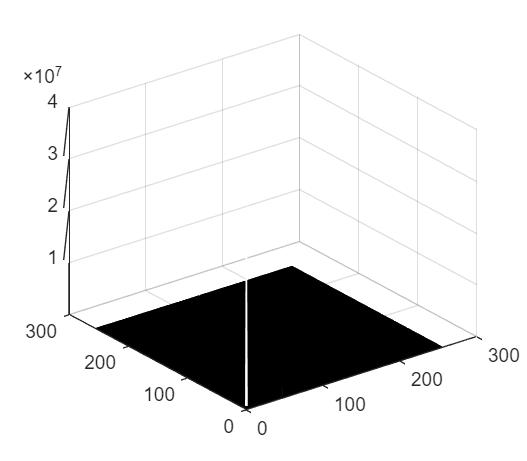



B_lp_frek = fft2(B2_filt_lp);
mesh(abs(B_lp_frek(1:256, 1:256)));

uppgift 4) 

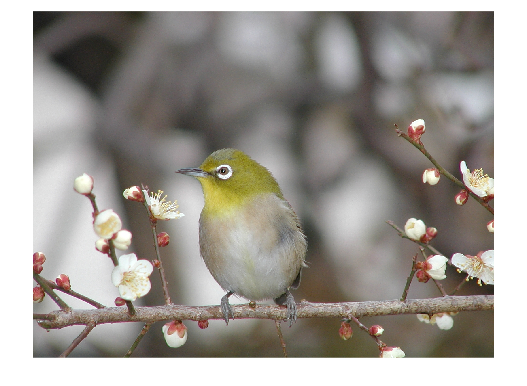

clf

Bird = imread('Bird_lab3.jpg');
imshow(Bird);

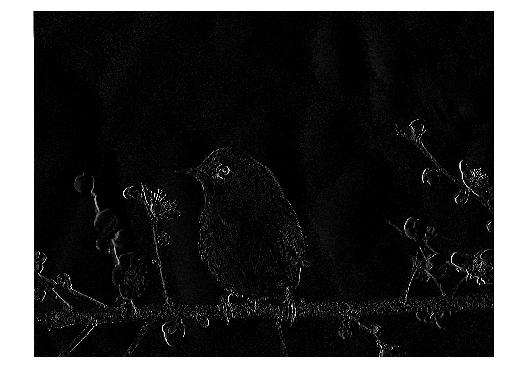

Bird_black = rgb2gray(Bird);

Bird_black_filt_ver = uint8(conv2(single(h_hp),single(Bird_black)));
Bird_black_filt_hor = uint8(conv2(single(transpose(h_hp)),single(Bird_black)));

figure(10); imshow(Bird_black_filt_ver);

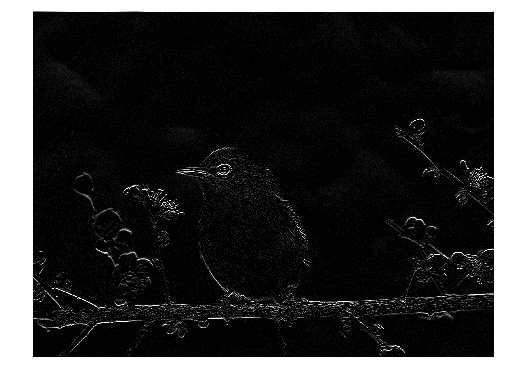

figure(11); imshow(Bird_black_filt_hor);

## Del 2

uppgift 5)

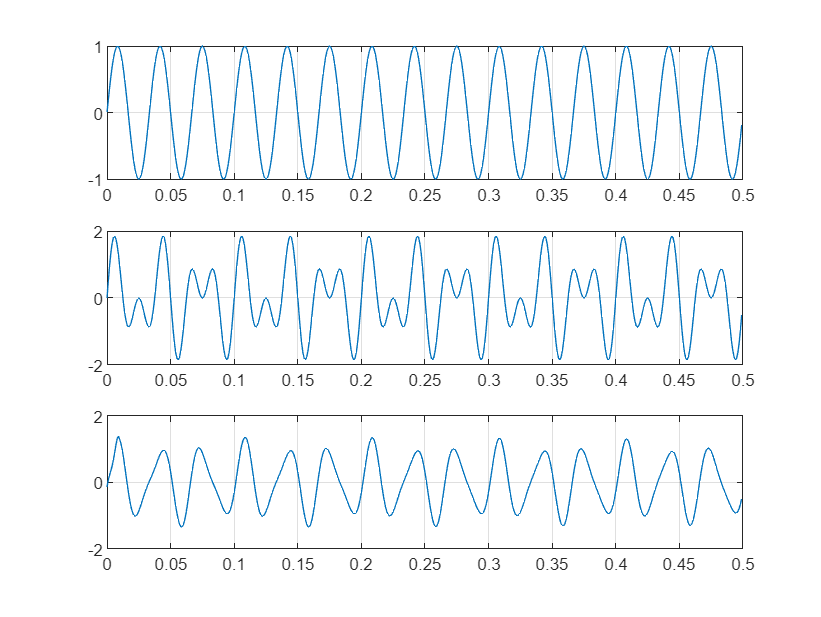

clear 
clf

t = 0:0.001:2;

x_storn = sin(2*pi*50.*t); % Skapa störning 50 Hz
x_storn2 = 0.6*sin(2*pi*50.5.*t + pi/7); % Skapa approx. av störningen
x_signal = sin(2*pi*30.*t); % Skapa signal 30 Hz
x_bland =x_storn + x_signal; % Blanda
P = con2seq(x_storn2); % Indata till adaptivt filter
T = con2seq(x_bland); % Önskade data (”target”)

pr = [-1 1];
s = 1;

id = [0 1 2 3 4 5 6 7 8 9 10]; % Fördröjningar, 10 stycken, ej 11 !!
lr = 0.01; % learning rate
net = newlin(pr, s, id, lr);
Pi = {0 0 0 0 0 0 0 0 0 0}; % Obs 10 stycken
passes = 50; % epoker

for i = 1:passes;
[net,y,e,Pf,Af,tr] = adapt(net,P,T,Pi); % Adaptera, tar lite tid !!
end


subplot(311); plot(t(1:500),x_signal(1:500)); grid;
subplot(312); plot(t(1:500),x_bland(1:500)); grid;
subplot(313); plot(t(1:500),[e{1:500}]); grid;

uppgift 6)

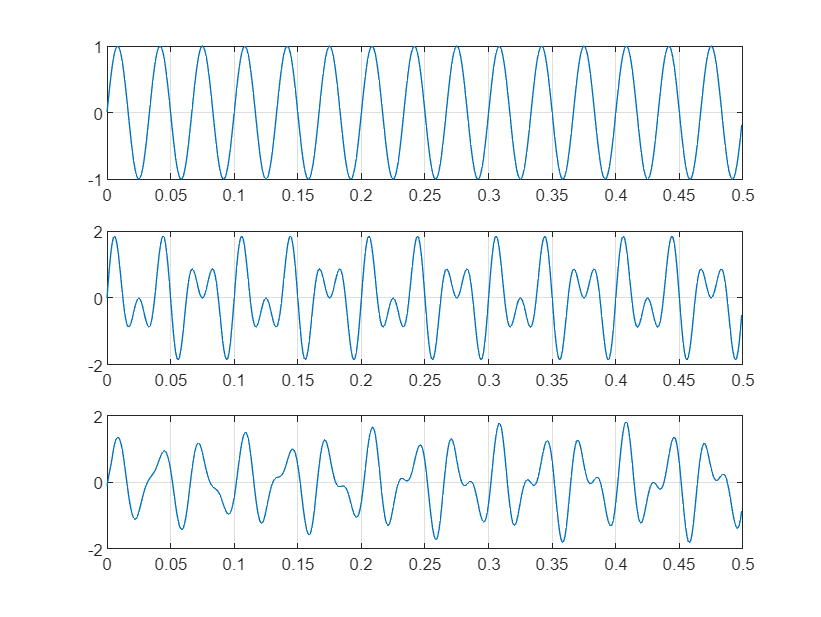


clear 
clf

t = 0:0.001:2;

x_storn = sin(2*pi*50.*t); % Skapa störning 50 Hz
x_storn2 = 0.6*sin(2*pi*50.5.*t + pi/7); % Skapa approx. av störningen
x_signal = sin(2*pi*30.*t); % Skapa signal 30 Hz
x_bland =x_storn + x_signal; % Blanda
P = con2seq(x_storn2); % Indata till adaptivt filter
T = con2seq(x_bland); % Önskade data (”target”)

pr = [-1 1];
s = 1;

id = [0 1 2 3 4 5]; % Fördröjningar, 10 stycken, ej 11 !!
lr = 0.01; % learning rate
net = newlin(pr, s, id, lr);
Pi = {0 0 0 0 0}; % Obs 10 stycken
passes = 50; % epoker

for i = 1:passes;
[net,y,e,Pf,Af,tr] = adapt(net,P,T,Pi); % Adaptera, tar lite tid !!
end


subplot(311); plot(t(1:500),x_signal(1:500)); grid;
subplot(312); plot(t(1:500),x_bland(1:500)); grid;
subplot(313); plot(t(1:500),[e{1:500}]); grid;

uppgift 7)

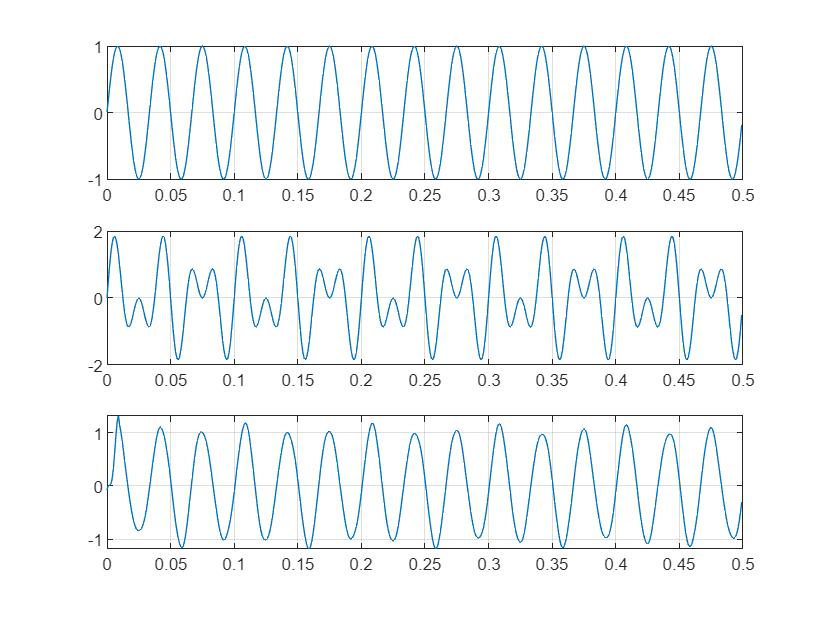

clear 
clf

t = 0:0.001:2;

x_storn = sin(2*pi*50.*t); % Skapa störning 50 Hz
x_storn2 = 0.6*sin(2*pi*50.5.*t + pi/7); % Skapa approx. av störningen
x_signal = sin(2*pi*30.*t); % Skapa signal 30 Hz
x_bland =x_storn + x_signal; % Blanda
P = con2seq(x_storn2); % Indata till adaptivt filter
T = con2seq(x_bland); % Önskade data (”target”)

pr = [-1 1];
s = 1;

id = [0 1 2 3 4 5 6 7 8 9 10]; % Fördröjningar, 10 stycken, ej 11 !!
lr = 0.04; % learning rate
net = newlin(pr, s, id, lr);
Pi = {0 0 0 0 0 0 0 0 0 0}; % Obs 10 stycken
passes = 30; % epoker

for i = 1:passes;
[net,y,e,Pf,Af,tr] = adapt(net,P,T,Pi); % Adaptera, tar lite tid !!
end


subplot(311); plot(t(1:500),x_signal(1:500)); grid;
subplot(312); plot(t(1:500),x_bland(1:500)); grid;
subplot(313); plot(t(1:500),[e{1:500}]); grid;

uppgift 8

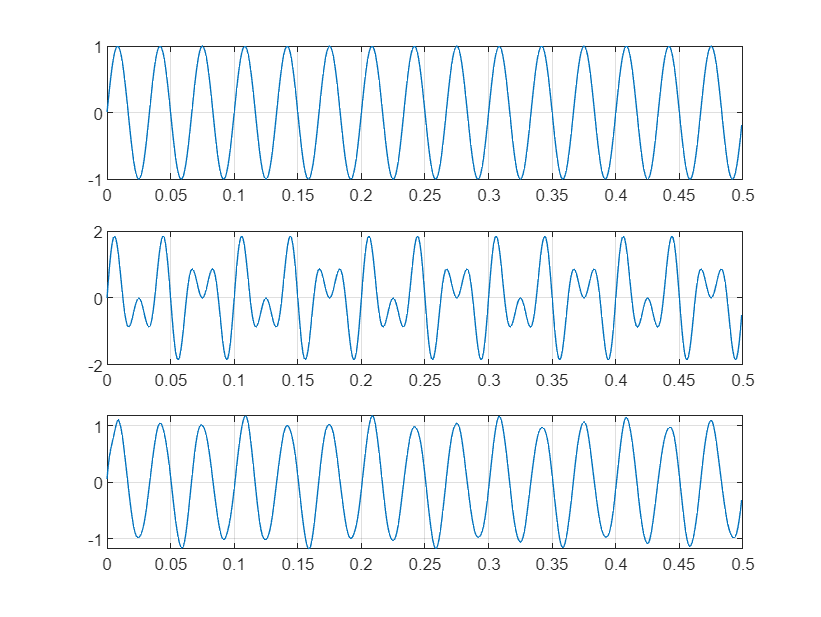

clear 
clf

t = 0:0.001:2;

x_storn = sin(2*pi*50.*t); % Skapa störning 50 Hz
x_storn2 = 0.6*sin(2*pi*50.5.*t + pi/7); % Skapa approx. av störningen
x_signal = sin(2*pi*30.*t); % Skapa signal 30 Hz
x_bland =x_storn + x_signal; % Blanda
P = con2seq(x_storn2); % Indata till adaptivt filter
T = con2seq(x_bland); % Önskade data (”target”)

pr = [-1 1];
s = 1;

id = [0 1 2 3 4 5 6 7 8 9 10]; % Fördröjningar, 10 stycken, ej 11 !!
lr = 0.040; % learning rate
net = newlin(pr, s, id, lr);
Pi = {0 0 0 0 0 0 0 0 0 0}; % Obs 10 stycken
passes = 8; % epoker

for i = 1:passes;
[net,y,e,Pf,Af,tr] = adapt(net,P,T,Pi); % Adaptera, tar lite tid !!
end


subplot(311); plot(t(1:500),x_signal(1:500)); grid;
subplot(312); plot(t(1:500),x_bland(1:500)); grid;
subplot(313); plot(t(1:500),[e{1:500}]); grid;


%Kvalitetsmått
median(abs(x_signal(1:500) - [e{1:500}]))

ans = 0.0469

mean(abs(x_signal(1:500) - [e{1:500}]))

ans = 0.0575

sum(abs(x_signal(1:500) - [e{1:500}]))

ans = 28.7743


mean(pow2(abs(x_signal(1:500) - [e{1:500}]))) %inspererat av minstakvadratmetoden

ans = 1.0412